## AAE364 HW5 MATLAB CODE

## problem 1 >> B-5-10

s = tf('s');
G = 10/(s^2+2*s+10);

fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE364\matlab\matlab_output';

% Impulse reponse
impF = 1;
[num_imp, den_imp] = tfdata(G*impF);
output_impulse = return_inverseLaplace_expression(num_imp, den_imp)

$$output\_impulse = \frac{10\,\sin\left(3\,t\right)}{3}\,{\mathrm{e}}^{-t}$$

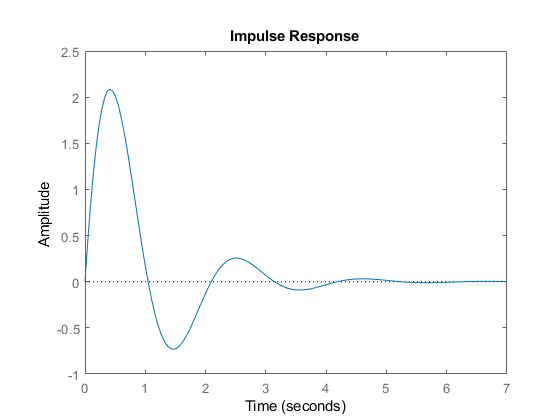

fig1 = figure("Renderer","painters");
impulse(G);
saveas(fig1, fullfile(fdir,'HW5_b_5_10_impulse.png'));


% Step Response
stepF = 1/s;
[num_step, den_step] = tfdata(G*stepF);
output_step = return_inverseLaplace_expression(num_step, den_step)

$$output\_step = \left(-\cos\left(3\,t\right)-\frac{\sin\left(3\,t\right)}{3}\right)\,{\mathrm{e}}^{-t}+1$$

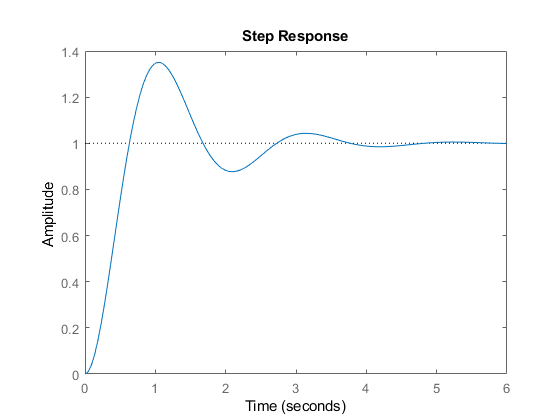

fig2 = figure("Renderer","painters");
step(G);
saveas(fig2, fullfile(fdir,'HW5_b_5_10_step.png'));


% Ramp Response
rampF = 1/s^2;
[num_ramp, den_ramp] = tfdata(G*rampF);
output_ramp = return_inverseLaplace_expression(num_ramp, den_ramp)

$$output\_ramp = \left(\frac{\cos\left(3\,t\right)}{5}-\frac{4\,\sin\left(3\,t\right)}{15}\right)\,{\mathrm{e}}^{-t}+t-\frac{1}{5}$$

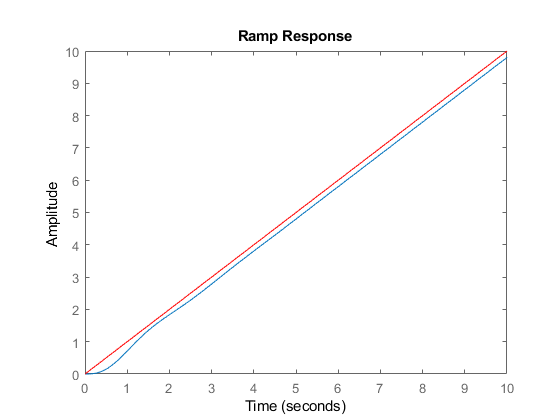

fig3 = figure("Renderer","painters");
step(G / s);  
ylim([0, 10])
xlim([0, 10])
hold on
plot(linspace(0,10,20), linspace(0,10,20), '-r')
hold off
title('Ramp Response')
saveas(fig3, fullfile(fdir,'HW5_b_5_10_ramp.png'));

## problem 2

MOS = 15;  % percent
zeta = calc_zetaFromMOS_or_MOSFromzeta(MOS, "zeta")

zeta = 0.5169